# Data modelling & simulation coursework code

## Question 1

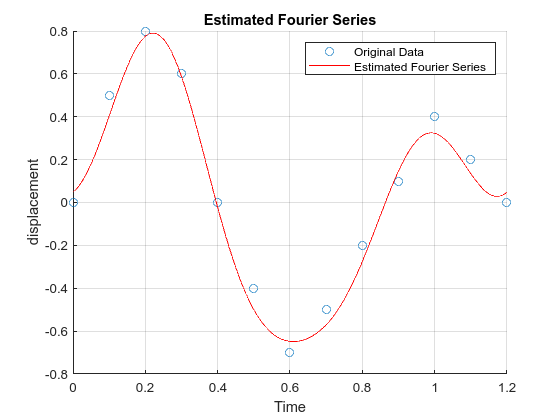

%%## Question 1a
clear

%% Defined Variables
x = 0:0.1:1.2;
y = [0, 0.5, 0.8, 0.6, 0, -0.4, -0.7, -0.5, -0.2, 0.1, 0.4, 0.2, 0];

n_max = 3; % number of Fourier terms

%% Estimated variable functions
T = x(end) - x(1);
a0 = (1/T) * trapz(x, y);
an = zeros(1, n_max);
bn = zeros(1, n_max);

for n = 1:n_max
	an(n) = (2/T) * trapz(x, y .* cos(2*pi*n*x/T));
	bn(n) = (2/T) * trapz(x, y .* sin(2*pi*n*x/T));
end
  
%% find Fourier series

t = linspace(x(1), x(end), 1000); % create a finer time vector for plotting
ft = a0/2;
for n = 1:n_max
	ft = ft + an(n) * cos(2*pi*n*t/T) + bn(n) * sin(2*pi*n*t/T);
end
  
%% original data vs Fourier series plot

figure;
	scatter(x, y, 'o', 'DisplayName', 'Original Data');
	hold on;
	plot(t, ft, 'r-', 'DisplayName', 'Estimated Fourier Series');
	legend('show');
	title('Estimated Fourier Series');
	xlabel('Time');
	ylabel('displacement');
	grid on;

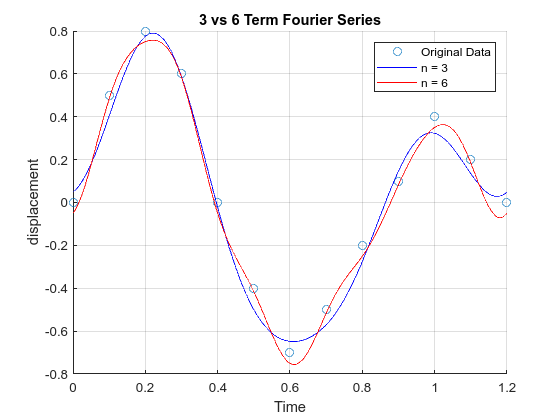

%%## Question 1b
clear
%% Defined Variables
x = 0:0.1:1.2;
y = [0, 0.5, 0.8, 0.6, 0, -0.4, -0.7, -0.5, -0.2, 0.1, 0.4, 0.2, 0];
n_1ow = 3; % Lower number of Fourier terms
n_max = 6; % Highest number of Fourier terms

%% Estimated variable functions
T = x(end) - x(1);
a0 = (1/T) * trapz(x, y);
an = zeros(1, n_max);
bn = zeros(1, n_max);

for n = 1:n_max
    an(n) = (2/T) * trapz(x, y .* cos(2*pi*n*x/T));
    bn(n) = (2/T) * trapz(x, y .* sin(2*pi*n*x/T));
end

%% find Fourier series
ftl = a0/2; fth = a0/2;
t = linspace(x(1), x(end), 1000); % create a finer time vector for plotting

for n = 1:n_1ow
    ftl = ftl + an(n) * cos(2*pi*n*t/T) + bn(n) * sin(2*pi*n*t/T);
end
for n = 1:n_max
    fth = fth + an(n) * cos(2*pi*n*t/T) + bn(n) * sin(2*pi*n*t/T);
end

%% original data vs Fourier series plot
figure;
scatter(x, y, 'o', 'DisplayName', 'Original Data');
hold on;
plot(t, ftl, 'b', 'DisplayName', 'n = 3');
hold on;
plot(t, fth, 'r-', 'DisplayName', 'n = 6');
legend('show');
title('3 vs 6 Term Fourier Series');
xlabel('Time');
ylabel('displacement');
grid on;

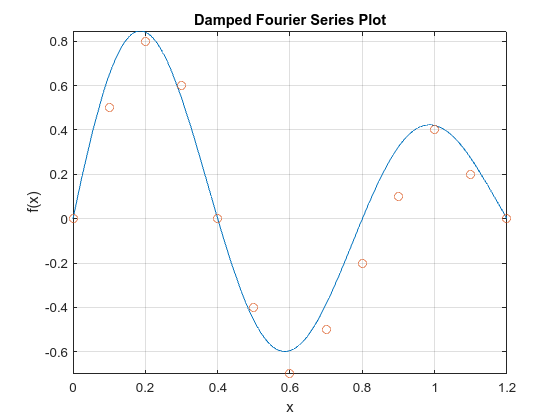

%%% my aprox function plot
clear

Data_x = 0:0.1:1.2;
Data_y = [0, 0.5, 0.8, 0.6, 0, -0.4, -0.7, -0.5, -0.2, 0.1, 0.4, 0.2, 0];

syms x;
n = 1;
T = 0.8;
L = T/2;
a0 = 0;
an = 0;
alpha = log(2) / T;

% Calculate bn terms and damped Fourier series expression
f_x = a0;
for n_val = 1:n
    bn = 1;%(2 / L) * int(x^2 * sin(n_val * pi * x / L) * exp(-alpha * x), 0, L);
    f_x = f_x + (bn * sin(n_val * pi * x / L)) * exp(-alpha * x);
end

% Plotting
figure;
fplot(f_x, [0, 1.2]);
hold on
scatter(Data_x, Data_y, 'o', 'DisplayName', 'Original Data');
title('Damped Fourier Series Plot');
xlabel('x');
ylabel('f(x)');
grid on;

## Question 2

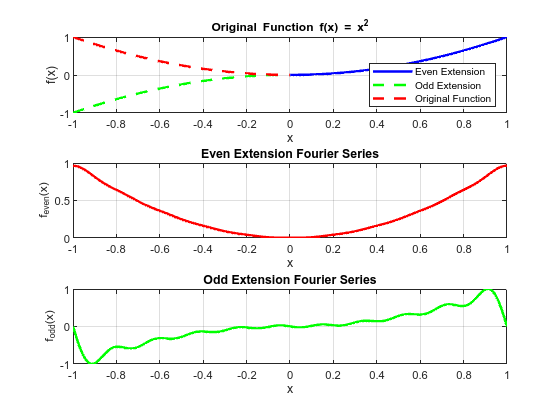

%% Qestion 2b
clear
%% Def variables
L = 1; % Length of the interval
x = linspace(-1, L, 1000); % set resoloution
f = @(x) x.^2; % function
N = 10; % num of terms 
a0 = 1/L * integral(@(x) f(x), 0, L);
a_n = zeros(1, N); % even coefficent
b_n = zeros(1, N); % odd coeficient
for n = 1:N 
    % evaluate a_n
    a_n(n) = 2/L * integral(@(x) f(x) .* cos(n * pi * x / L), 0, L);
    % evaluate b_n
    b_n(n) = 2/L * integral(@(x) f(x) .* sin(n * pi * x / L), 0, L);
end

%% Plots
figure;
    % Original function
    subplot(3, 1, 1);
        % plot origional function in given interval
        plot(x(x >= 0), f(x(x >= 0)), 'b-', 'LineWidth', 2);
        hold on
        % plot exact odd extension
        plot(x(x <= 0), -flipud(f(x(x <= 0))), 'g--', 'LineWidth', 2);
        hold on
        % plot exact even extension
        plot(x(x <= 0), f(x(x <= 0)), 'r--', 'LineWidth', 2);
        title('Original Function f(x) = x^2');
        xlabel('x');
        ylabel('f(x)');
        grid on;
        legend({'Even Extension','Odd Extension', 'Original Function'},'Location', 'southeast');
    % Even extension Fourier series
    subplot(3, 1, 2);
        f_even = zeros(size(x));
        f_even = f_even + a0; % a0 needs to be acocunted for in even extension
        for n = 1:N
            f_even = f_even + a_n(n) * cos(n * pi * x / L);
        end
        plot(x, f_even, 'r-', 'LineWidth', 2);
        title('Even Extension Fourier Series');
        xlabel('x');
        ylabel('f_{even}(x)');
        grid on;
    % Odd extension Fourier series
    subplot(3, 1, 3);
        f_odd = zeros(size(x));
        for n = 1:N
            f_odd = f_odd + b_n(n) * sin(n * pi * x / L);
        end
        plot(x, f_odd, 'g-', 'LineWidth', 2);
        title('Odd Extension Fourier Series');
        xlabel('x');
        ylabel('f_{odd}(x)');
        grid on;
    hold off

## question 3

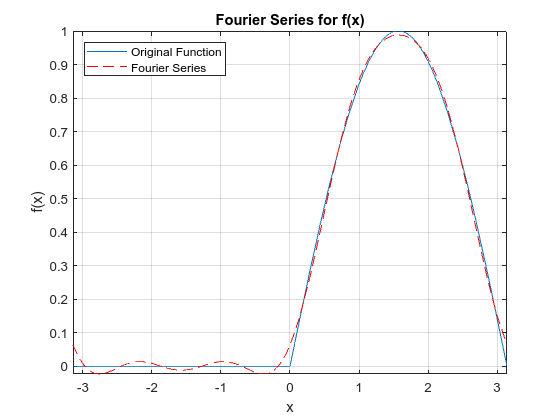

clear
% definitions
syms x;% Symbolic variable
f = piecewise(-pi <= x < 0, 0, 0 <= x <= pi, sin(x));% Define the piecewise function
T = 2*pi;% Period of the function
a0 =(1/T) * int(f, -pi, pi);% Calculate a_0  2/pi;%
n = 5;% Number of terms in the Fourier series

% Initialize coefficients
an = zeros(1, n);
bn = zeros(1, n);

% Calculate a_n and b_n terms
for n = 1:n
    an(n) = (1/pi) * int(f * cos(n*x), -pi, pi);
    bn(n) = (1/pi) * int(f * sin(n*x), -pi, pi);
end

% Construct Fourier series
f_fourier = a0;
for n = 1:n
    f_fourier = f_fourier + an(n) * cos(n*x) + bn(n) * sin(n*x);
end

% Plotting
figure;
    fplot(f, [-pi, pi], 'DisplayName', 'Original Function');
    hold on
    fplot(f_fourier, [-pi, pi], 'r--', 'DisplayName', 'Fourier Series');
    title('Fourier Series for f(x)');
    xlabel('x');
    ylabel('f(x)');
    legend('Location', 'northwest');
    grid on;
    hold off;

## plot my series

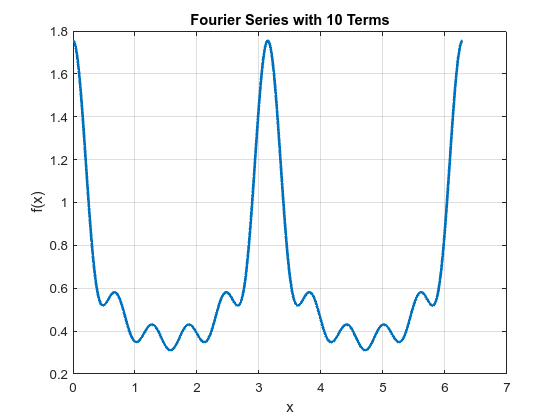

clear
% Define the function f(x)
f = @(x, N) (2/pi) + sum((2 + 2*cos(pi*(1:N)))./(pi + pi*(1:N)) .* cos((1:N)' .* x), 2);
% f = @(x, N) (2/pi) + sum(((-1)^(n+1) / ((2*n-1)*(2*n+1))) .* cos((1:N)' .* x), 2);
% Define the range of x values
x_values = linspace(0, 2*pi, 1000);

% Set the number of terms in the series (adjust as needed)
N_terms = 10;

% Initialize y_values with the constant term
y_values = (2/pi)*ones(size(x_values));

% Calculate the Fourier series terms and update y_values
for n = 1:N_terms
    term = (2 + 2*cos(pi*n))/(pi + pi*n) * cos(n * x_values);
    y_values = y_values + term;
end

% Plot the function
figure;
plot(x_values, y_values, 'LineWidth', 2);
title(['Fourier Series with ', num2str(N_terms), ' Terms']);
xlabel('x');
ylabel('f(x)');
grid on;

## plot given funciton

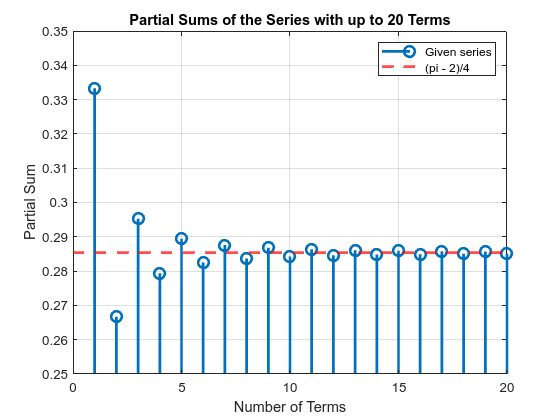


% Define the function for the series
f = @(n) (-1)^(n+1) / ((2*n-1)*(2*n+1));
% f = @(n) (2 + 2*cos(n*pi)) / (pi + n*pi);
% Define the number of terms in the series
N_terms = 20;

% Initialize an array to store partial sums
partial_sums = zeros(1, N_terms);

% Calculate partial sums
for n = 1:N_terms
    partial_sums(n) = sum(arrayfun(f, 1:n));
end

% Plot the partial sums
figure;
stem(1:N_terms, partial_sums, 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Given series');
hold on 
yline((pi - 2)/4, 'r--', 'LineWidth', 2, 'DisplayName', '(pi - 2)/4');
ylim([0.25, 0.35]);
title(['Partial Sums of the Series with up to ', num2str(N_terms), ' Terms']);
legend
xlabel('Number of Terms');
ylabel('Partial Sum');
grid on;

## Question 4

## Adjusting k1s code

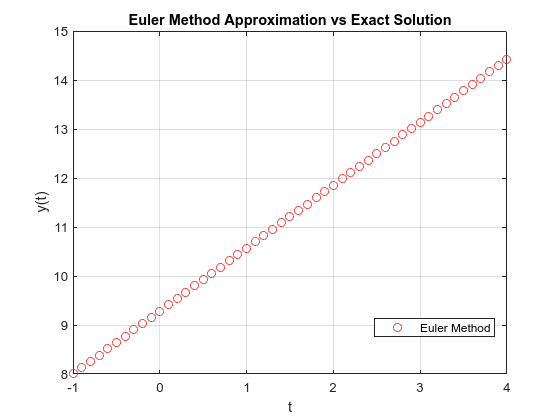

h = 0.1;   % Step size
x = -1:h:4; % x interval definition
y = zeros(size(x));
y(1) = 8;   % Initial condition
n = numel(y);

dydx = ((x.*y.^2)+2)/(3-y.*x.^2); %@(x, y) (2 * x * y^2 + 4) / (2 * (3 - y * x^2))
% Define the ODE function
for i = 1:n-1
    % Update y using the Euler method
    y(i+1) = y(i) + h * dydx;
end

% Plot the results
figure;
plot(x, y, 'ro', 'DisplayName', 'Euler Method');
hold on;

% Plot the exact solution for comparison
%f1 = (3+sqrt(-4.*x.^2.*(x-3)+9))/x.^2;
%plot(x, f1, 'b', 'DisplayName', 'Exact Solution');
grid on;

% Add labels and legend
xlabel('t');
ylabel('y(t)');
title('Euler Method Approximation vs Exact Solution');
legend('Location', 'Best');

## my code

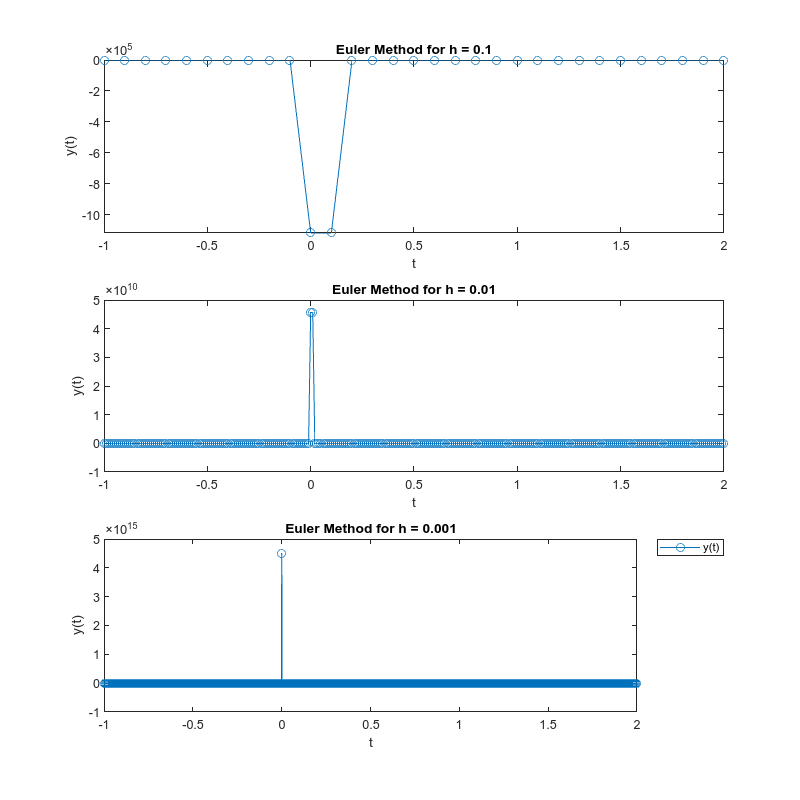

clear
% definitions
f = @(x, y) (2 * x * y^2 + 4) / (2 * (3 - y * x^2));% the ODE function
tspan = [-1, 2];% Time interval
x0 = -1; y0 = 8;% Initial conditions
h_values = [0.1, 0.01, 0.001];% Step sizes

% Plotting
figure;
for h = h_values
    % arrays to log results
    x_values = x0:h:tspan(2);
    y_values = zeros(size(x_values));
    
    % Set initial condition
    x_values(1) = x0;
    y_values(1) = y0;
    
    % Euler method
    for i = 1:length(x_values)-1
        y_prime = f(x_values(i), y_values(i));
        y_values(i+1) = y_values(i) + h * y_prime;
    end

    % Plot the result
    subplot(3, 1, find(h_values == h));
    plot(x_values, y_values, 'o-', 'DisplayName', ['h = ' num2str(h)]);
    % Labels
    xlabel('t');
    ylabel('y(t)');
    title(['Euler Method for h = ' num2str(h)]);
end
legend({'y(t)'},'Location', 'Bestoutside');
set(gcf, 'Position', [100, 100, 800, 800]);

## Exact solution

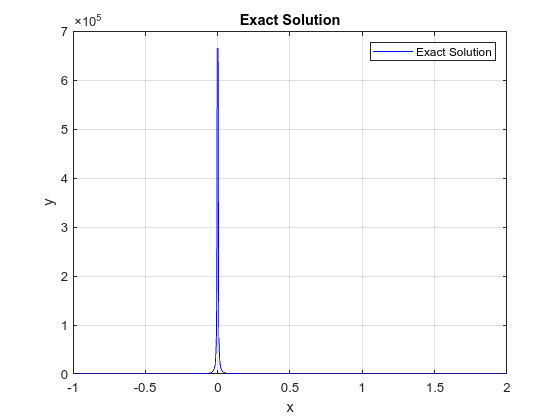

figure;
x = linspace(-1,2,1000);
Es = (3 + sqrt((-4 * x.^2 .* (x - 3) + 9))) ./ x.^2;
plot(x, Es, 'b', 'DisplayName', 'Exact Solution');
xlabel('x');
ylabel('y');
title('Exact Solution');
grid on;
legend('Location', 'northeast');

## Going further

## Without peak at 0

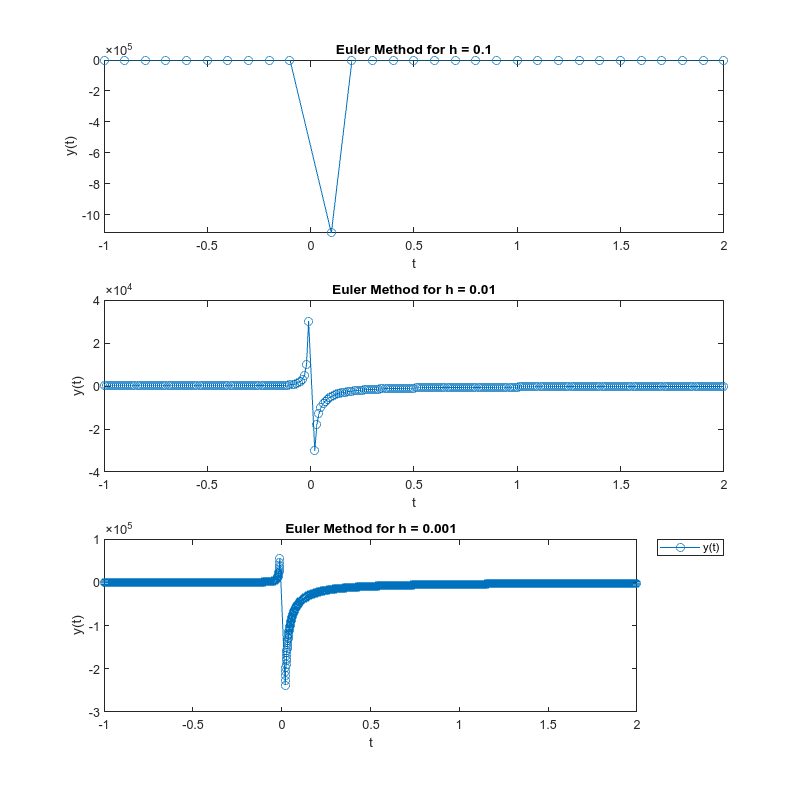

figure;
for h = h_values
    % Initialize arrays to store results
    x_values = x0:h:tspan(2);
    y_values = zeros(size(x_values));
    
    % Set initial condition
    x_values(1) = x0;
    y_values(1) = y0;
    
    for i = 1:length(x_values)-1
        y_prime = f(x_values(i), y_values(i));
        y_values(i+1) = y_values(i) + h * y_prime;
    end
    
    % Plot the result
    subplot(3, 1, find(h_values == h));
    %plot(x_values, y_values, 'o-', 'DisplayName', ['h = ' num2str(h)]);
    plot(x_values(x_values >= 0.02 | x_values <= -0.01), y_values(x_values >= 0.02 | x_values <= -0.01), 'o-', 'DisplayName', ['h = ' num2str(h)]);
    %ylim([-5, 25]);  % Constrain y-axis to
    hold on;
    
    % Display the legend in the last subplot
    if h == h_values(end)
        legend('Location', 'Best');
    end
    hold off;
    % Label the axes
    xlabel('t');
    ylabel('y(t)');
    title(['Euler Method for h = ' num2str(h)]);
end
legend({'y(t)'},'Location', 'Bestoutside');
set(gcf, 'Position', [100, 100, 800, 800]);

## Differentiating

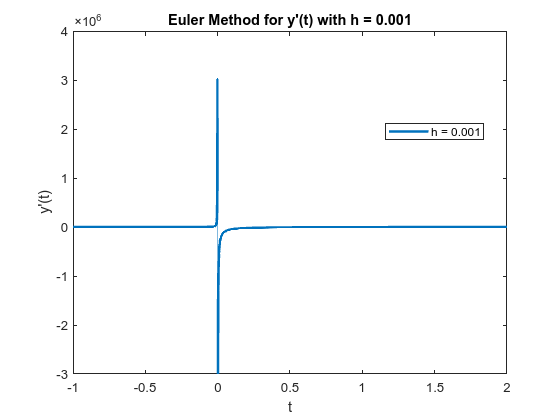

% Definitions
f = @(t, y) (2 * t * y^2 + 4) / (2 * (3 - y * t^2));  % ODE function (y')
tspan = [-1, 2];  % Time interval
x0 = -1; y0 = 8;  % Initial conditions
h_values = [0.1, 0.01, 0.001];  % Step sizes

% Plotting
figure;
for h = h_values(3)
    % Initialize arrays to store results
    t_values = x0:h:tspan(2);
    y_prime_values = zeros(size(t_values));
    
    % Set initial condition
    t_values(1) = x0;
    y_prime_values(1) = f(t_values(1), y0);  % Use the ODE function for initial condition
    
    % Euler method for y' (derivative)
    for i = 1:length(t_values)-1
        y_prime = f(t_values(i), y_prime_values(i));
        y_prime_values(i+1) = y_prime_values(i) + h * y_prime;
    end
    
    % Plot the result
    plot( find(h_values == h));
    plot(t_values(t_values >= 0.002 | t_values <= -0.001), y_prime_values(t_values >= 0.002 | t_values <= -0.001), '-','LineWidth', 2, 'DisplayName', ['h = ' num2str(h)]);
    hold on;
    
    % Display the legend in the last subplot
    if h == h_values(end)
        legend('Location', 'Best');
    end
    
    % Label the axes
    xlabel('t');
    ylabel('y''(t)');
    title(['Euler Method for y''(t) with h = ' num2str(h)]);
end

## Integrating

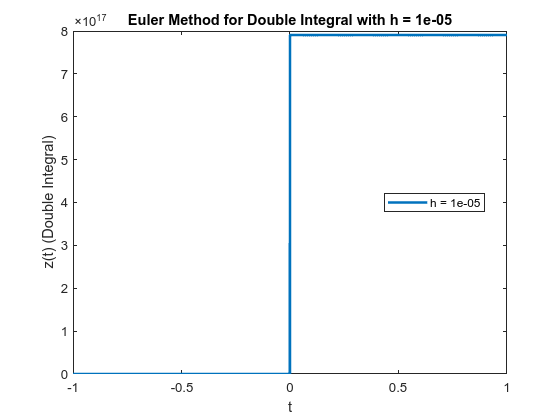

% Definitions
f = @(t, y) (2 * t * y^2 + 4) / (2 * (3 - y * t^2));  % ODE function (y')
tspan = [-1, 1];  % Time interval
x0 = -1; y0 = 8;  % Initial conditions
h_values = [0.1, 0.01, 0.001, 0.00001];  % Step sizes

% Plotting
figure;
for h = h_values(4)
    % Initialize arrays to store results
    t_values = x0:h:tspan(2);
    y_values = zeros(size(t_values));
    z_values = zeros(size(t_values));
    
    % Set initial conditions
    t_values(1) = x0;
    y_values(1) = y0;
    z_values(1) = 0;  % Initial condition for the double integral
    
    % First Euler method for y (integral)
    for i = 1:length(t_values)-1
        y_prime = f(t_values(i), y_values(i));
        y_values(i+1) = y_values(i) + h * y_prime;
    end
    
    % Second Euler method for the double integral (z)
    for i = 1:length(t_values)-1
        z_prime = y_values(i);  % Integrate y to get z'
        z_values(i+1) = z_values(i) + h * z_prime;
    end
    
    % Plot the result
    plot(find(h_values == h));
    plot(t_values, z_values, '-','LineWidth', 2, 'DisplayName', ['h = ' num2str(h)]);
    hold on;
    
    % Display the legend in the last subplot
    if h == h_values(end)
        legend('Location', 'Best');
    end
    
    % Label the axes
    xlabel('t');
    ylabel('z(t) (Double Integral)');
    title(['Euler Method for Double Integral with h = ' num2str(h)]);
end